**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP5: Régulation en courant et en vitesse d’une machine à courant continu 

## 1) Mesure de R (MCC2)

Mesure 1 : $I=1\ldotp 7A\;;U=6\ldotp 52V\;;R=\frac{U}{I}=3\ldotp 83\Omega$

Mesure 2 : $I=1A\;;U=4\ldotp 28V\;;R=\frac{U}{I}=4\ldotp 28\Omega$

Mesure 3 : $I=0\ldotp 56A\;;U=2\ldotp 38V\;;R=\frac{U}{I}=4\ldotp 25\Omega$


$$R_{\textrm{moyenne}} =4\ldotp 12\Omega$$


## 2) Mesure de Kφ (MCC2)

Mesure 1 : $E=-13\ldotp 1V\;;N=-107\;\textrm{rad}/s\to K_{\varphi } =\frac{E_{\textrm{moy}} }{\Omega_{\textrm{moy}} }=0\ldotp 1224$

Mesure 1 : $E=-26V\;;N=212\;\textrm{rad}/s\to K_{\varphi } =0\ldotp 1226$

Mesure 1 : $E=-38V\;;N=313\ldotp 6\;\textrm{rad}/s\to K_{\varphi } =0\ldotp 1211$


$$E_{\textrm{moy}} =-25\ldotp 7V\;\;\;\;;\Omega_{\textrm{moy}} =-210\ldotp 9\;\textrm{rad}/s\to K_{\varphi } =0\ldotp 1218$$


## 3) Mesure de L (MCC2)


$$\alpha =50%\;;U=29\ldotp 4V\;;\Delta i=222\ldotp 5\textrm{mA}$$



$$\Delta i=\alpha U\left(1-\alpha \right)\times L\times f\iff L=\frac{\Delta i}{\alpha U\left(1-\alpha \right)\times f}=\frac{0\ldotp 2225}{60\times 0\ldotp 5\left(1-0\ldotp 5\right)\times 10e^3 }=1\ldotp 483\mu F$$


#### Calculer la constante de temps électrique de la machine. 

## 4) Déterminer de la constante de temps mécanique du banc

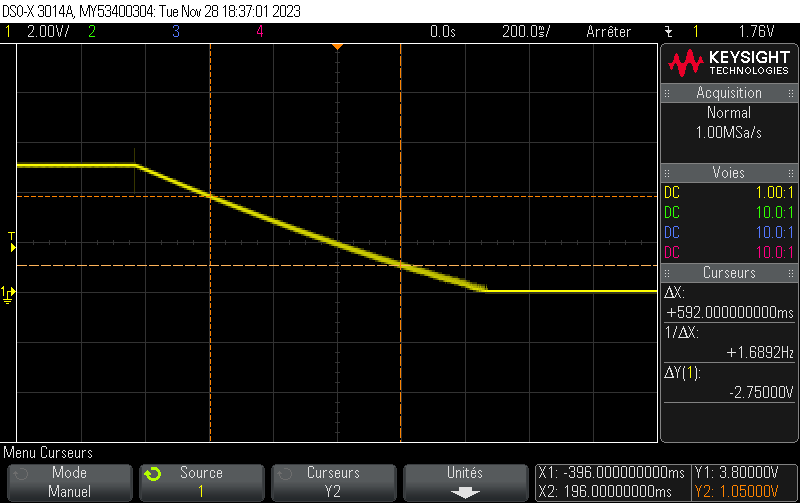

A $t_1 ,\;x_1 =400\textrm{ms}\;\textrm{et}\;y_1 =3\ldotp 8V\Rightarrow \Omega_1 =$ ; A $t_2 ,\;x_2 =820\textrm{ms}\;\textrm{et}\;y_2 =1\ldotp 05V$


$$\tau_m =\frac{t_1 }{\ln \left(\frac{\Omega \left(t_1 \right)-\Omega_0 }{\Omega \left(t_2 \right)-\Omega \left(t_1 \right)}\right)}=\frac{0\ldotp 400}{\ln \left(\frac{3\ldotp 8-5}{1\ldotp 05-3\ldotp 8}\right)}=-0\ldotp 48\;\left(\mathrm{ou}\;0\ldotp 48\;\mathrm{puisque}\;\mathrm{les}\;\mathrm{constantes}\;\mathrm{de}\;\mathrm{temps}\;\mathrm{sont}\;\mathrm{absolues}\ldotp \right)$$


## 5) Détermination des autres paramètres mécaniques du banc

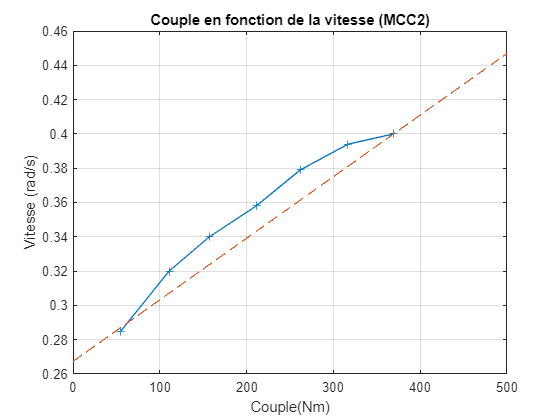

I=[285e-3 320e-3 340e-3 358e-3 379e-3 394e-3 0.4];
O=[525 1057 1500 2016 2500 3025 3529]*pi/30;
a = (I(6)-I(2))/(O(6)-O(2));
b = I(7)-a*O(7);
x = linspace(0,500,1000);
plot(O,I,'-+',x,a.*x+b,'--');
title('Couple en fonction de la vitesse (MCC2)')
xlabel('Couple(Nm)'); ylabel('Vitesse (rad/s)')
grid on

fprintf("I0 est égal à %f A",b)

I0 est égal à 0.267304 A


$$C_S =K_{\varphi } \times I_0 =0\ldotp 1218\times 0\ldotp 2673=0\ldotp 0326$$



$$f=K_{\varphi } \times \frac{I_1 -I_0 }{\Omega_1 }=1\ldotp 68e^{-4}$$



$$J=f\times \tau_m =1\ldotp 68e^{-4} \times 0\ldotp 48=4\ldotp 064e^{-5}$$


## 6) Essai en boucle ouverte  

Pour vitesse induit à 1992 tr/min.

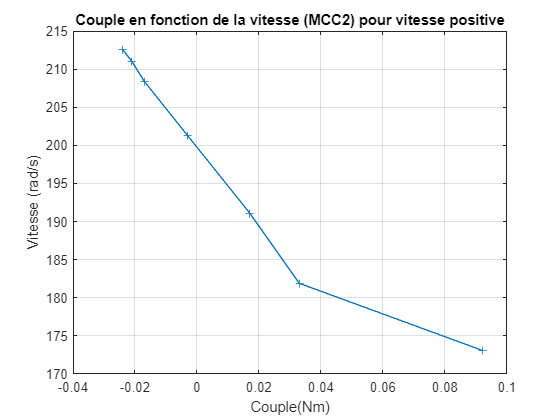

Couple_MCC2=[-0.024 -0.021 -0.017 -0.003 0.017 0.033 0.092];
Omega_MCC2=[2030 2015 1990 1922 1825 1737 1653]*pi/30;
plot(Couple_MCC2,Omega_MCC2,'-+');
title('Couple en fonction de la vitesse (MCC2) pour vitesse positive')
xlabel('Couple(Nm)'); ylabel('Vitesse (rad/s)')
grid on

Pour vitesse induit à -2066 tr/min

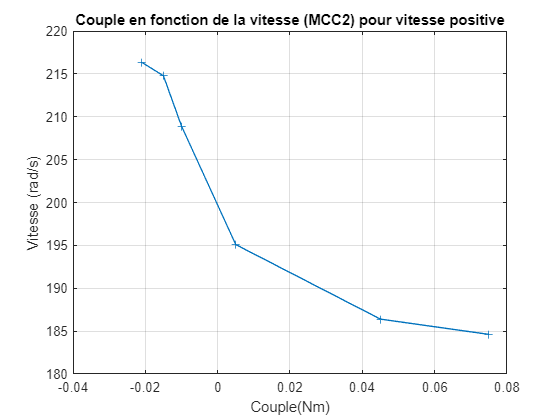

Couple_MCC2b=[-0.021 -0.015 -0.010 0.005 0.045 0.075];
Omega_MCC2b=[2066 2051 1995 1863 1780 1763]*pi/30;
plot(Couple_MCC2b,Omega_MCC2b,'-+');
title('Couple en fonction de la vitesse (MCC2) pour vitesse positive')
xlabel('Couple(Nm)'); ylabel('Vitesse (rad/s)')
grid on

Nous pouvons observer aucune différence notable entre la courbes pour une vitesse positive et une vitesse négative. On peut donc en conclure que le sens de rotation n'influence pas la sur la variation de la vitesse de rotation par rapport au couple du moteur.

## 7)Régulation de courant 

Consigne de courant=1A==>Couple= ? A avec $R_1 =R_2 =33k\Omega \;\mathrm{et}\;C_1 =22\mathrm{nF}$.

### Avec une consigne positive:

Couple_MCC2c=[-0.103  -0.131  -0.171 -0.150];
Omega_MCC2c=[3998 3583 2556 1397]*pi/30;

Le courant dans l'induit ne dépasse pas la valeur de la consigne. Quand ce courant devrait dépasser la consigne,  une consigne négative:

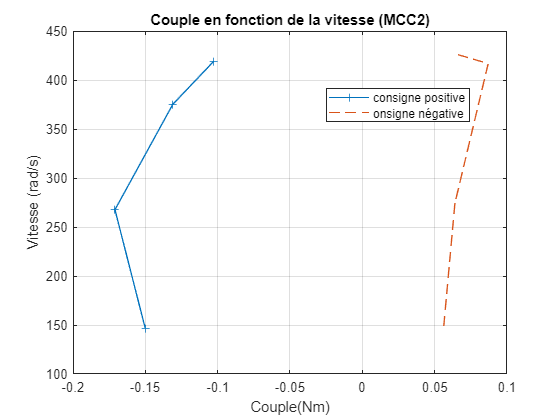

Couple_MCC2d=[0.066 0.087 0.064 0.056];
Omega_MCC2d= [4067 3980 2619 1375]*pi/30;

plot(Couple_MCC2c,Omega_MCC2c,'-+',Couple_MCC2d,Omega_MCC2d,'--');
title('Couple en fonction de la vitesse (MCC2)')
xlabel('Couple(Nm)'); ylabel('Vitesse (rad/s)')
legend("consigne positive","onsigne négative","Location","best")
grid on

Diminuer la tension d'alimentation diminuera également le alpha, ce qui réduira la vitesse du moteur et ceux qu'importe le sens de rotation de ce dernier. 

## 8) Réponse à l’échelon de courant 

Observations qualitatives

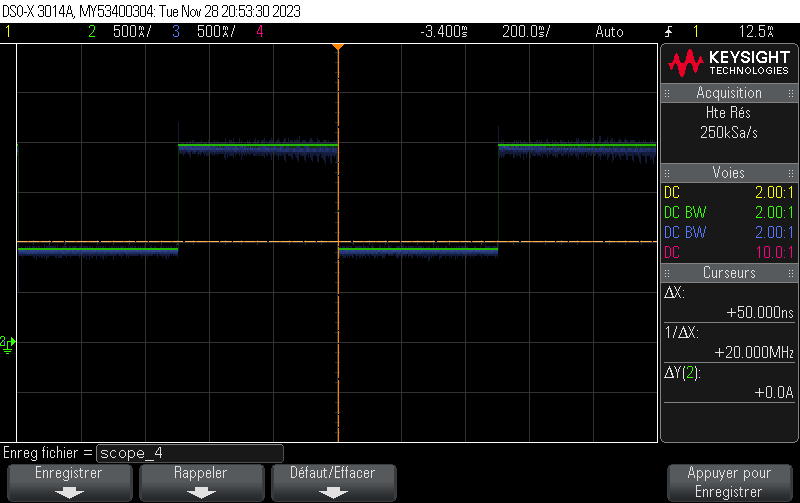

Le GBF a pour rôle de commander la vitesse du moteur en lui envoyant une tension de consigne. Dans notre cas, nous faisons osciller cette tension de commande entre +/- 0.5V.

Ainsi, quand la tension est positive, le moteur tourne dans le sens horaire alors que si cette tension est négative, alors il tournera dans le sens antihoraire. 

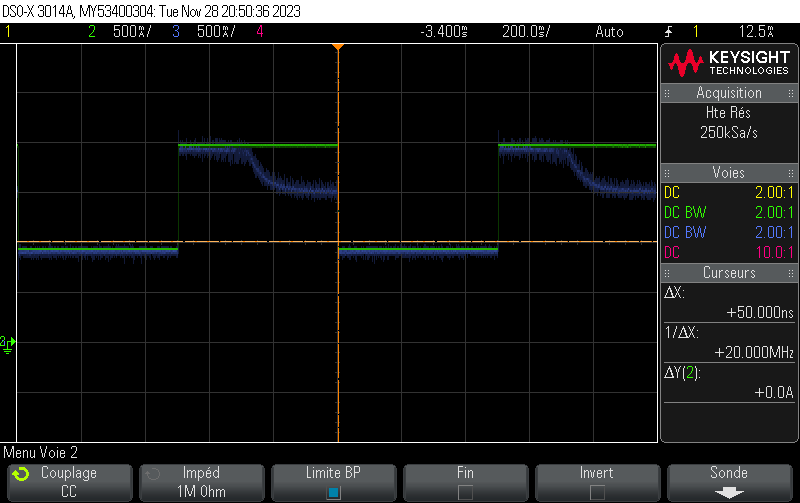

Dans un second temps, nous avons diminué la valeur du réostat.

En faisant ceci, nous observons que la vitesse du moteur n'est pas constante durant les demi-périodes de son oscillation (contrairement à précédement) : en réduisant le réostat, nous réduisons la résistance, et donc le courant disponible pour le moteur, ce qui fait diminuer sa vitesse. Si le moteur parvient à attendre sa vitesse de consigne au démarrage, cela est due à la résistance provoquée par l'inertie du moteur au passage de statique -> mouvement.

En conclusion, cette structure de régulation permet de commander la vitesse et le sens de rotation du moteur à l'aide d'une tension. Ces régulations sont quasi-instantanées et précises, mais ne peuvent pas corriger des problèmes liées aux composants tel que la charge du moteur (trop faible réduite) . 